# 6. Considere a cadeia de Markov com o diagrama de transicao de estados seguinte:

## a) Defina em Matlab a matriz de transicao de estados T, com Tij sendo a probabilidade de ir do estado j para o estado i num unico passo.

%   1 2 3 4 5
%  1
%  2
%  3
%  4
%  5

T = [0.8 0 0 0.3 0
    0.2 0.6 0 0.2 0
    0 0.3 1 0 0
    0 0.1 0 0.4 0
    0 0 0 0.1 1]

T =     0.8000         0         0    0.3000         0
    0.2000    0.6000         0    0.2000         0
         0    0.3000    1.0000         0         0
         0    0.1000         0    0.4000         0
         0         0         0    0.1000    1.0000


## b) Faca um grafico com a probabilidade de comecando no estado 1, estar no estado 2 ao fim de n passos, com n a variar de 1 ate 100. Justifique o que observa.

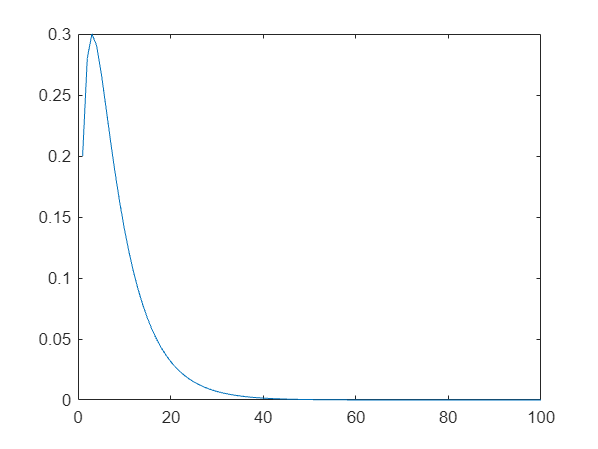

x = [1 0 0 0 0]';
probs3 = zeros(1,100);

for i = 1:100
    p = T^i*x;
    probs3(i) = p(2);
end

plot(probs3);

## c) Faca um grafico com a probabilidade de, comecando no estado 1, estar no estado 3 ao fim de n passos. Na mesma figura, faca um segundo grafico com a probabilidade de, comecando no estado 1, estar no estado 5 ao fim de n passos. Em ambos os casos, considere n a variar de 1 ate 100. Justifique o que observa.

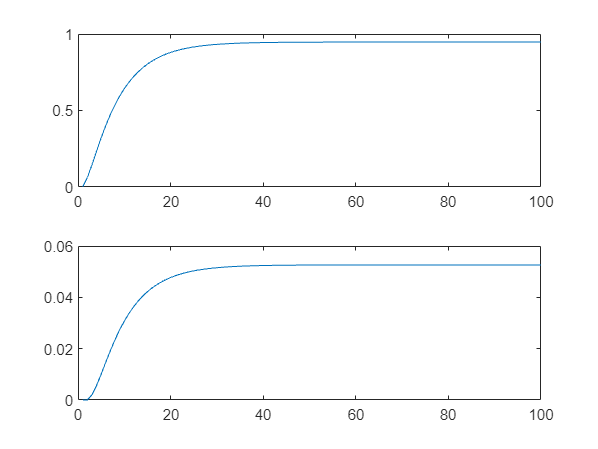

probs3 = zeros(1,100);
probs5 = zeros(1,100);

for i = 1:100
    p = T^i*x;
    probs3(i) = p(3);
    probs5(i) = p(5);
end

subplot(211)
plot(probs3)
subplot(212)
plot(probs5)


% 3 é um estado absorvente, entao converge para 1


## d) Determine a matriz Q.

% forma canonica
aux = [0.8 0   0.3 0 0
     0.2 0.6 0.2 0 0
     0   0.1 0.4 0 0
     0   0.3 0   1 0
     0   0   0.1 0 1];
% 2 estados absorventes criam entao uma matriz 2x2 no seu cantinho. é
% preciso trocar ordens de vez em quando, o 0.3 troca com o 0.1 na coluna
% 2, o 0.4 com o 0 na coluna 3 e o 1 com o 0.
Q = aux(1:3, 1:3)

Q =     0.8000         0    0.3000
    0.2000    0.6000    0.2000
         0    0.1000    0.4000


## e) Determine a matriz fundamental F

% F = (I - Q)^-1
F = (eye(3) - Q)^-1

F =     5.7895    0.7895    3.1579
    3.1579    3.1579    2.6316
    0.5263    0.5263    2.1053


## f) Qual a media (valor esperado) do numero de passos antes da absorcao comecando no estado 1? E comecando no estado 2? E se comecando no estado 4?

x1 = [1 0 0]';
x2 = [0 1 0]';
x4 = [0 0 1]';
fprintf("passos antes da absorcao comecando no E1 = %.2f, E2 = %.2f, E4 = %.2f\n", sum(F*x1), sum(F*x2), sum(F*x4));

passos antes da absorcao comecando no E1 = 9.47, E2 = 4.47, E4 = 7.89


## g) Comecando no estado 1, qual é a probabilidade de absorcao do estado 3? E do estado 5? Verifique a coerencia destes valores com o que observou na alinea 6 (c).

R = aux(4:5, 1:3); % slide 86
B = R*F; %slide 102 coluna comecar em estado transitorio e linha acabar no estado absovente
fprintf('Prob(estado 3) = %f, Prob(estado 5) = %f',B(1,1),B(2,1));

Prob(estado 3) = 0.947368, Prob(estado 5) = 0.052632